Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:02:42 |       43.75% |       70.20% |       1.1615 |       1.7760 |          0.0050 |
|       1 |          50 |       00:03:33 |       78.12% |       81.53% |       0.9805 |       0.5040 |          0.0050 |
|       1 |         100 |       00:03:58 |       87.50% |       83.33% |       0.3008 |       0.5498 |          0.0050 |
|       1 |         150 |       00:04:25 |       87.50% |       84.08% |       0.3780 |       0.5687 |          0.0050 |
|       

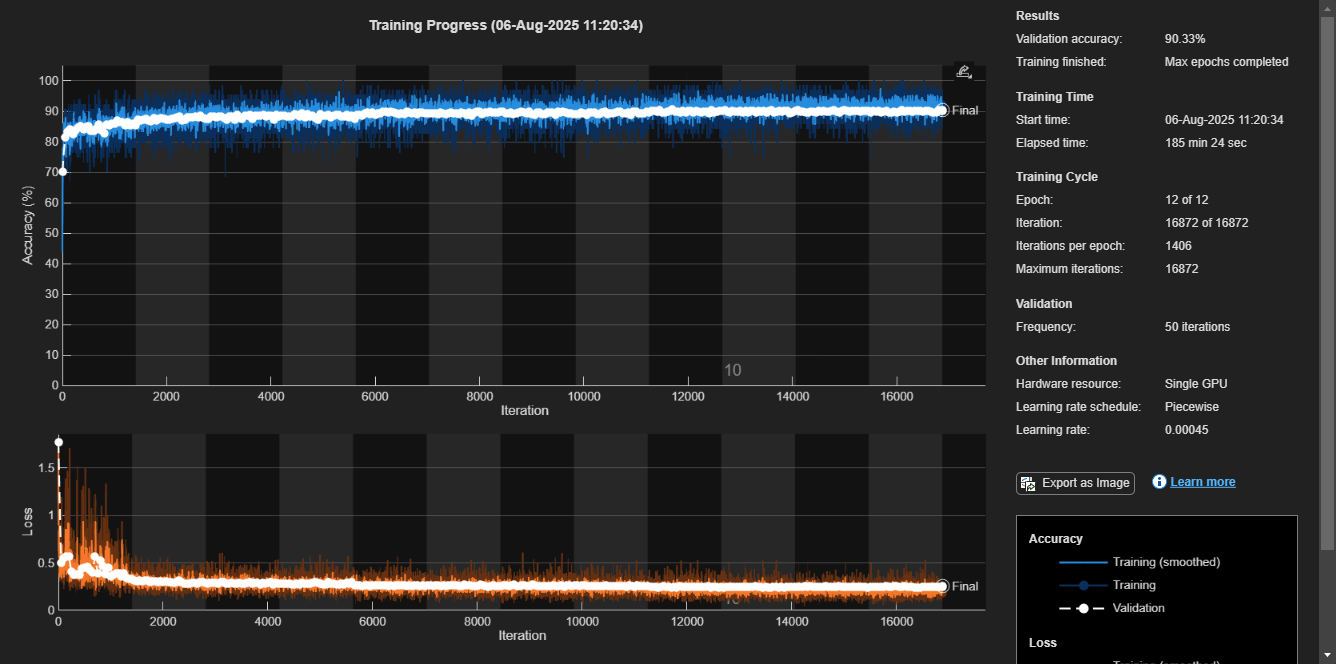

load('trainDataFin90k.mat'); 
load('valDataFin.mat');   

train_labels = categorical(train_labels);
val_labels = categorical(val_labels);

adsXTrain = arrayDatastore(train_dataset, 'IterationDimension', 4);
adsFTrain = arrayDatastore(train_features, 'IterationDimension', 4);
adsYTrain = arrayDatastore(train_labels, 'IterationDimension', 1);
dsTrain = combine(adsXTrain, adsFTrain, adsYTrain);

adsXVal = arrayDatastore(val_dataset, 'IterationDimension', 4);
adsFVal = arrayDatastore(val_features, 'IterationDimension', 4);
adsYVal = arrayDatastore(val_labels, 'IterationDimension', 1);
dsVal = combine(adsXVal, adsFVal, adsYVal);

if ~exist('checkpoints_fin', 'dir')
    mkdir('checkpoints_fin');
end

options = trainingOptions('adam', ...
    'InitialLearnRate', 5e-3, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.3, ...
    'LearnRateDropPeriod', 4, ...
    'L2Regularization', 1e-4, ...
    'MaxEpochs', 12, ...
    'MiniBatchSize', 64, ... 
    'Shuffle', 'every-epoch', ...
    'ValidationData', dsVal, ...
    'ValidationFrequency', 50, ...
    'CheckpointPath', 'checkpoints_fin/', ...
    'Verbose', true, ...
    'Plots', 'training-progress');


net = trainNetwork(dsTrain, lgraph, options);

save('finTrainedModelFin90k.mat', 'net');


